# Practica 1 - Robot Serie Personal

***NOTA:*** Se han elimiado los acentos debido a que la impresion pdf no los reconocia.

## 1. Generacion del objeto robot

A partir del trabajo previo realizado, mediante la tabla de Denavit-Hartenberg se ha creado un objeto robot para poder ser usado y simulado en Edubot.

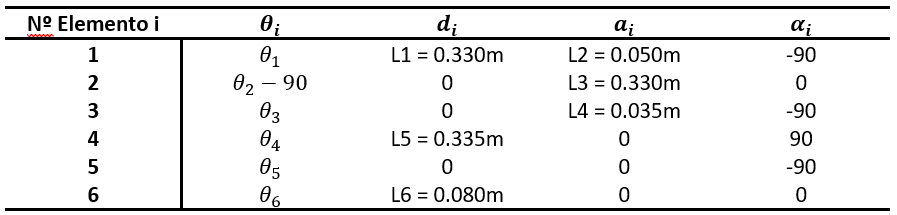

El comando **link **permite definir cada uno delos elementos del robot en base a la fila asociada de la tabla D-H.

L{i} = link ([$\alpha_i$    $a_i$    $\theta_i$    $d_i$])

***Nota:*** Las dimensiones longitdinales se han de implementar en metos, y las angulares en radianes.

L{1} = link([-pi/2  0.050  0      0.330]);      % Elemento 1
L{2} = link([0      0.330  -pi/2  0.000]);      % Elemento 2
L{3} = link([-pi/2  0.035  0      0.000]);      % Elemento 3
L{4} = link([pi/2   0.000  0      0.335]);      % Elemento 4
L{5} = link([-pi/2  0.000  0      0.000]);      % Elemento 5
L{6} = link([0      0.000  0      0.080]);      % Elemento 6

Mediante el comando **robot **se ha generado el objeto robot para ser usado por **Edubot.**

mirobot = robot(L,'LRMate200iD')

 
mirobot = 
 
LRMate200iD (6 axis, RRRRRR)
		grav = [0.00 0.00 9.81]		standard D&H parameters

  	alpha	 A	 theta	 D	R/P
	-1.5708	0.05	0	0.33	R	std
	0	0.33	-1.5708	0	R	std
	-1.5708	0.035	0	0	R	std
	1.5708	0	0	0.335	R	std
	-1.5708	0	0	0	R	std
	0	0	0	0.08	R	std
 


## 2. Problema cinematico directo e inverso utilizando Edubot

a)  Partiendo de la congiguracion artiqular $q_4$, calcular la localizacion TCP del robot $T_4$ usando el comando **fkine **y visualizarla mediante **plot**

q4 = [0 -pi/6 -pi/6 0 -pi/6 pi]     % (rad)

q4 =          0   -0.5236   -0.5236         0   -0.5236    3.1416



T4 = fkine(mirobot,q4)

T4 =     1.0000    0.0000    0.0000    0.0222
   -0.0000    1.0000    0.0000   -0.0000
   -0.0000   -0.0000    1.0000    1.0034
         0         0         0    1.0000


**VIsualizacion**

% plot(mirobot,q4)

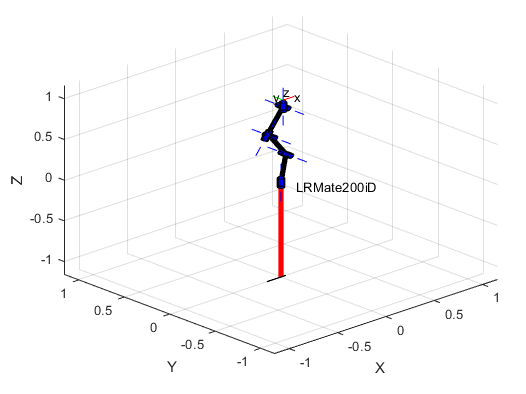

b)  Partiendo de $T_4$, usar la resolucion numerica general del problema cinematico inverso **ikine **para determinar la configuracion articular. ¿Se obtiene la misma confguracion de partida? ¿Es siempre asi? Probar al menos con dos configuraciones y semillas diferentes.

q4a = ikine(mirobot,T4)     % Utiliza la semilla q0a por defecto

q4a =     6.2832    6.7131  -14.9762    6.2832    6.6922   -9.4248


Utilizamos la semilla creada para el PUMA, $q_{0b} =\left\lbrack 0\;\;0\;\;0\;-\pi \;\;0\;\;\pi \right\rbrack$ (rad)

q0b = [0 0 0 -pi 0 pi]      % semilla q0b 

q0b =          0         0         0   -3.1416         0    3.1416


q4b = ikine(mirobot,T4, q0b)

q4b =    -3.1416    6.6263  -14.9513   -3.1416   -6.7542    3.1416


Nueva semilla $q_{0c} =\left\lbrack \pi \;\;0\;\;-\pi \;\;\;\;0\;\;\;\;0\;\;\;\;0\right\rbrack$ (rad)

q0c = [pi 0 -pi 0 0 0]      % semilla q0c

q0c =     3.1416         0   -3.1416         0         0         0


q4c = ikine(mirobot,T4,q0c)

q4c =     3.1416    0.3431   -2.3849   -0.0000    0.4710    0.0000


**Representaciones**

% plot(mirobot,q4a)

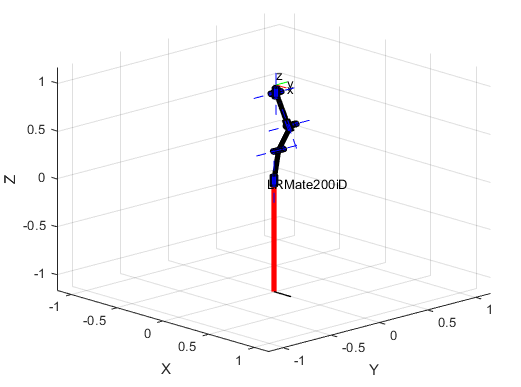

% plot(mirobot,q4b)

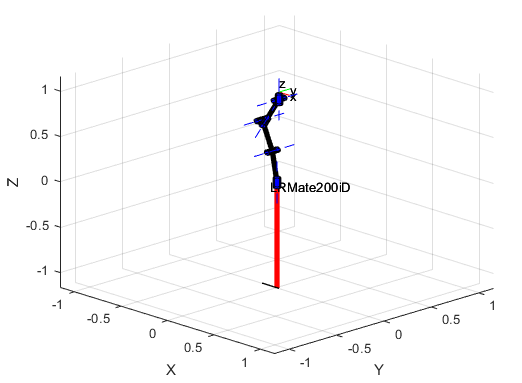

% plot(mirobot,q4c)

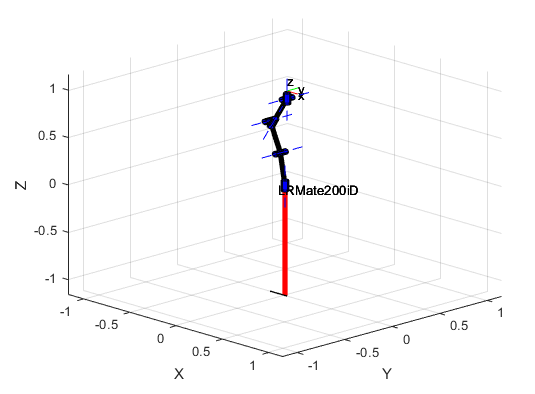

**Conclusiones**

Como se puede observar la configuracion varia, pero la posicion de la punta es la misma en los tres casos.

## 3. Programacion del problema cinematico directo

En base a los parametros de Denavit-Hartenberg anteriormente calculados, se ha definido una funcion de matlab, **mi_fkine**, que devuelve la localizacion del TCP en forma de matriz de transformacion homogenea **T** ante cualquier configuracionarticular **q.**

Para definir esta funcion, se ha considerado las matrices de transformacion que conectan los sistemas de refrencia asociados a cada articulacion, segun el metodo de Denavit-Hartenberg.

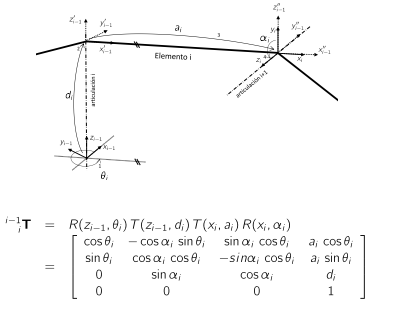

***Nota: ***Hay un error en la matriz T de la imagen superior, T(1,3) es producto de senos.

Esta matriz puede ser generada de forma sencilla a patir de los parametros de DH usando el siguiente comando 

Se ha utilizado al funcion creada para comprobar si los resultados de los comandos **fkine** y el de **mi_fkine** son iguales ante diversas configuraciones articulares

q5 = [pi/3 pi 0 pi/2 -pi/2 0];

T5_fkine = fkine(mirobot,q5)

T5_fkine =     0.5000    0.0000    0.8660   -0.0732
    0.8660   -0.0000   -0.5000   -0.2868
   -0.0000    1.0000   -0.0000   -0.0350
         0         0         0    1.0000


T5_mi_fkine = mi_fkine(q5)

T5_mi_fkine =     0.5000    0.0000    0.8660   -0.0732
    0.8660   -0.0000   -0.5000   -0.2868
   -0.0000    1.0000   -0.0000    0.2600
         0         0         0    1.0000


Probamos con otra configuracion

q6  = [-pi pi/2 0 pi/6 pi -pi/2]

q6 =    -3.1416    1.5708         0    0.5236    3.1416   -1.5708



T6_fkine = fkine(mirobot,q6)

T6_fkine =    -0.5000    0.8660    0.0000   -0.4150
   -0.8660   -0.5000   -0.0000   -0.0000
   -0.0000   -0.0000    1.0000    0.0750
         0         0         0    1.0000


T6_mi_fkin = mi_fkine(q6)

T6_mi_fkin =    -0.5000    0.8660    0.0000   -0.1200
   -0.8660   -0.5000   -0.0000   -0.0000
   -0.0000   -0.0000    1.0000    0.0750
         0         0         0    1.0000


**Funcion **

function M = mi_fkine(q)
T01 = denavit(q(1),     0.330,  0.050, -pi/2);
T12 = denavit(q(2)-pi/2,0,      0.035,     0);
T23 = denavit(q(3),     0,      0.035, -pi/2);
T34 = denavit(q(4),     0.335,  0,      pi/2);
T45 = denavit(q(5),     0,      0,     -pi/2);
T56 = denavit(q(6),     0.080,  0,         0);

M = T01*T12*T23*T34*T45*T56;

end

**Conclusion **

Como se puede observar se obtiene practicamente los mismo resultados. La diferencia en la posicion pz puede deberse a error de calculo numerico de MATLAB.